`例 在`**0≤t≤2pi**`区间内，绘制曲线`**y=3cost+1**`。`  

t=0:pi/100:2*pi;
y=3*cos(t)+1;
figure
plot(t,y)

`例 已知`**t**`的范围是`**0**`到`**2π**`， `**x=2*t;y=t.*sin(t).*sin(t)**`，请画出关于`**x**`、 `**y**`的曲线图。`

t=0:0.1:2*pi;
x=2 * t;
y=t.*sin(t).*sin(t);
plot(x, y);

  `例 已知`**x=rand(4, 4)**`， `**y=randn(4,4)**`，请画出关于`**x**`、 `**y**`的曲线图。`  

x = rand(4, 4);
y = randn(4, 4);
figure
plot(x,y,'LineWidth',1)

`例 已知`**x=[0:pi]; y=2*sin(4*x).**`，试用`**line**`函数绘图。`  

x=0:1/pi:pi;
y=2*sin(4*x);
% 绘制直线
figure
line(x, y,'linestyle','-','color','r')

`例 已知`**x=[0:pi]; y=[0:pi];z=2*sin(4.*x.*y)**`，试用`**line**`函数绘图。`  

x=[0:pi];
y=[0:pi];
z=2*sin(4.*x.*y);
% 绘制直线
figure
line(x, y, z) %需要在figure里去旋转图像
view([-6.05 14.69])

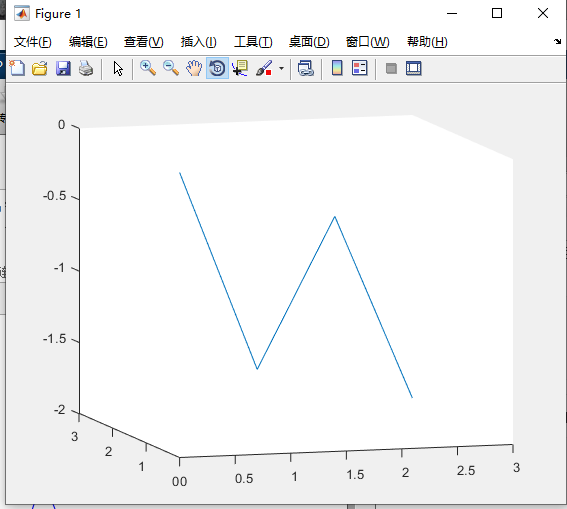

`例 利用`**polar**`函数绘制轮胎图。`  

%设定角度
theta=0:45;
%设定对应角度的半径
rho=ones(1,length(theta));
%绘图
figure
polar(theta,rho)

Step by step illustration:

for i=0:45
theta=[i i+1];
rho=[1 1];
polar(theta,rho,'r');
hold on;
pause(1);
end

`例 利用`**polar**`函数在极坐标下进行绘图。`  

% 角度
t = 0:.01:2*pi;
%设定对应角度的半径
r = sin(2*t).*cos(2*t);
% 绘图
figure
polar(t, r, 'r')

例 以单位阵A和全1阵B为输入进行图形绘制。

% 生成单位阵
A = eye(4);
% 生成全1阵
B = ones(4);
%绘图
figure
plot(A,B)

`例 尝试绘制正余弦双曲线图。`  

x=-pi:0.1:pi;
% 产生数据
y=sin(2*x+pi/3);
y1=cos(3*x+pi/3);
% 绘图
plot(x,y,'k',x,y1,'r','LineWidth',3);

`例 尝试绘制不同长度的正弦曲线图。`  

t1 = -pi:0.01:pi;
t2 = 0:0.01:pi/2;
% 产生数据
y1 = sin(2*t1+pi/3);
y2 = sin(3*t2+pi/3);
% 绘图
plot(t1, y1, 'k-','LineWidth',5);
hold on;
plot(t2, y2, 'r-.', 'LineWidth', 2)

`例 用不同标度在同一坐标内绘制曲线`**y1=0.2e-0.5xcos(4πx) **`和`**y2=2e-0.5xcos(πx)**

x=0:pi/100:2*pi;
% 生成曲线
y1=0.2*exp(-0.5*x).*cos(4*pi*x);
y2=2*exp(-0.5*x).*cos(pi*x);
% 绘图
figure
plotyy(x,y1,x,y2);
plot(x, y1, 'k-', x, y2, 'k-.','LineWidth', 3)

**例 用不同标度在同一坐标内绘制曲线y1=0.2e-0.5xcos(4πx) 和y2=2e-0.5xcos(πx)。**

MATLAB程序如下：

x=0:pi/100:2*pi;
% 生成曲线
y1=0.2*exp(-0.5*x).*cos(4*pi*x);
y2=2*exp(-0.5*x).*cos(pi*x);
% 绘图
figure
plotyy(x,y1,x,y2);
plot(x, y1, 'k-', x, y2, 'k-.', 'LineWidth', 3)

`例 现在举一个简单的调用`  **plotyy(x1,y1,x2,y2, fun1, fun2)**`的例子。`  

% 生成横轴数据
x1=1:0.1:100;
x2=x1;
% 生成纵轴数据
y1=x1;
y2=x2.^3;
% 利用不同的函数绘图
figure
plotyy(x1,y1,x2,y2,@plot,@semilogy)

`例 用`**contour**`函数画`**peaks**`函数。`  

z = peaks(40);
figure
contour(z, 'k')

例 用contour函数画sinxcosy的等高线。

x = 0:0.1:pi;
y = 0:0.1:pi;
% 生成坐标系
[xx,yy] = meshgrid(y,x);
% 生成曲面
z = sin(xx).*cos(yy);
% 绘制等高线
figure
contour(xx,yy,z, 'k');

`例 现在对上例中的等高线加上适当的标准。`  

x = 0:0.1:pi;
y = 0:0.1:pi;
% 生成坐标系
[xx,yy] = meshgrid(y,x);
% 生成曲面
z = sin(xx).*cos(yy);
% 绘图，加标注
figure
[C, h] = contour(xx,yy,z);
clabel(C, h);

`例 计算矩阵`**A**`等高线为`**2**`和`**3**`的坐标位置。`  

A = [1 2 3 4;2 3 4 5;3 4 5 6];
contourc(A,[2 3])

`例 设矩阵`**A=randn(5, 5)**`，在`**MATLAB**`中将`**A**`的每一列绘制出一条曲线。`  

% 生成矩阵
A=randn(5, 5);
% 绘图
figure
plot(A(1,:),'-*');
hold on
plot(A(2,:),'-v');
hold on
plot(A(3,:),'-+');
hold on
plot(A(4,:),'-.');
hold on
plot(A(5,:),'-');

`例 在同一坐标内，分别用不同线型和颜色绘制曲线`**y1=0.2e-0.5xcos(4πx) **`和`   **y2=2e-0.5xcos(πx)**  

% 横坐标轴
x = linspace(0, 2*pi, 100);
% 生成数据点，纵坐标轴
y1 = 0.2 * exp(-0.5 * x).* cos(4 * pi * x);
y2 = 2 * exp(-0.5 * x) .* cos(pi * x);
% 绘图
figure
plot(x, y1, 'r-.', x, y2, 'k:', 'LineWidth',4);

`例 设置正弦曲线的线宽为`**3**`，设置上三角形进行数据点的标记，并设置标记点边缘为黑色，设置标记点填充颜色为红色，设置标记点的尺寸为`

**10**`。`  

% 横坐标轴
x = linspace(0, 2*pi, 50);
% 生成数据点，纵坐标轴
y = 2 * sin(pi * x);
% 绘图
figure
% 设置线的宽带为3
plot(x, y, 'k--^', 'LineWidth', 3, ...
'MarkerEdgeColor', 'k', ... % 设置标记点的边缘颜色为黑色
'MarkerFaceColor', 'r', ... % 设置标记点的填充颜色为红色
'MarkerSize', 10) % 设置标记点的尺寸为10

`例 绘制正弦曲线，设置图形的标题为`  **y=sin**`（`**x**`）。`  

% 横坐标轴
x = linspace(0, 2*pi, 50);
% 生成数据点，纵坐标轴
y = 2 * sin(pi * x);
% 绘图
figure
% 设置线宽为3
plot(x, y, 'k--^', 'LineWidth', 3)
% 设置标题
title('y=sin(\alpha)的曲线')

`例 绘制正弦曲线，设置图形的标题为`**y=sin**`（`**x**`），设置`**x**`轴的标注为`**x**`，设置`**y**`轴的标注为`**sin**`（`**x**`）`  

% 横坐标轴
x = linspace(0, 2*pi, 50);
% 生成数据点，纵坐标轴
y = 2 * sin(pi * x);
% 绘图
figure
% 设置线宽为3
plot(x, y, 'k--^', 'LineWidth', 3)
% 设置标题
title('y=sin(x)的曲线')
% 设置x轴的标注
xlabel('x')
% 设置y轴的标注
ylabel('sin(x)')

`例 绘制正弦和余弦曲线，设置图形的标题、 `**x**`轴和`**y**`轴的标注、设置曲线标准。`  

% 横轴
x=0:pi/50:2*pi;
% 曲线数据
y1=sin(x);
y2=cos(x);
% 绘图
figure
plot(x, y1, 'k-', x, y2, 'k-.')
% 文本标注
text(pi, 0.05, '\leftarrow sin(\alpha)')
text(pi/4-0.4, 0.05, 'cos(\alpha)\rightarrow')
% 标题标注
title('sin(\alpha) and cos(\alpha)')
% 坐标轴标注
xlabel('\alpha')
ylabel('sin(\alpha) and cos(\alpha)')

`例 绘制抛物线和三次幂曲线，设置图形的标题、 `**x**`轴和`**y**`轴的标注、设置曲线文本标准、设置图例标注`

% 横轴
x = -2:.1:2;
% 曲线数据
y1 = x.^2;y2 = x.^3;
% 绘图
figure
plot(x,y1, 'r-', x, y2, 'b:')
% 标题标注
title('y=x^2和y=x^3曲线')
% 坐标轴标注
xlabel('x')
ylabel('y')
% 文本标注
gtext('y = x^2', 'FontName', 'Times New Roman','FontSize', 16)
gtext('y = x^3', 'FontName', 'Times New Roman','FontSize', 16)
% 图例标注
legend('\ity=x^2', '\ity=x^3')
%l = legend('\color{black}\bf legend entry 1','\color{red} legend entry 2');
%legend boxoff

`例 绘制抛物线，产生等长刻度的坐标轴。`  

% 横轴
x = -2:.1:2;
% 曲线数据
y1 = x.^2;
% 绘图
figure
plot(x,y1, 'r-')
% 标题标注
title('y=x^2曲线')
% 产生等长刻度坐标轴
axis equal

`例 观察曲线`**y=cos(tan(πx))**`在`**x=0.5**`附近的图形曲线。`

% x轴
x = 0:1/3000:1;
% 生成误差曲线
y = cos(tan(pi*x));
% 绘图
figure
% 分裂窗口为2*1个子窗口
subplot(2,1,1)
plot(x,y)
title('\itcos(tan(\pix))')
% 坐标轴调整
subplot(2,1,2)

`例 设置坐标轴字体为新罗马，字号位`**16**`号加粗斜体。`

% 横轴
x = -2:.1:2;
% 曲线数据
y1 = x.^2;
% 绘图
figure
plot(x,y1, 'r-')
% 标题标注
title('y=x^2曲线')
% 设置坐标轴字体
set(gca,'FontName', 'Tmie New Roma', 'FontSize',16, 'FontWeight', 'Bold', 'FontAngle', 'italic')

`例 设置坐标轴`**X**`轴逆转，坐标轴边框的颜色为红色，线宽为`**5**`号。`  

% 横轴
x = -2:.1:2;
% 曲线数据
y1 = x.^2;
% 绘图
figure
plot(x,y1, 'r-')
% 标题标注
title('y=x^2曲线')
% 设置坐标轴边框
set(gca,'XDir', 'reverse', 'XColor', 'r','LineWidth', 5)

`例 设置坐标轴刻度。`  

% 横轴
x = 0:.1:2;
% 曲线数据
y1 = x.^2;
% 绘图
figure
plot(x,y1, 'r-')
% 标题标注
title('y=x^2曲线')
% 设置坐标刻度
set(gca, 'XTick', [0: .5: 2])
set(gca, 'YTick', [0: .5: 4])
set(gca, 'XTickLabel', {'x=0', 'x=0.5', 'x=1', 'x=1.5', 'x=2'})

`例 设置坐标轴坐标轴位置。`  

% 横轴
x = 0:.1:2;
% 曲线数据
y1 = x.^2;
% 绘图
figure
plot(x,y1, 'r-')
% 标题标注
title('y=x^2曲线')
% 设置坐标位置
set(gca, 'Position', [0.1 0.2 0.3 0.4])

`例 在同一坐标中，可以绘制`**3**`个同心圆，增加网格线，关闭坐标边框。`

% 横轴
t = 0:0.01:2*pi;
x = exp(i * t);
% 曲线数据
y = [x; 2*x; 3*x]';
% 绘图
figure
plot(y)
% 加网格线
grid on;
% 关闭坐标边框
box off;
% 坐标轴采用等刻度
axis equal

  `例 利用`**subpot**`函数绘制多个子图。`  

x=-3:1:9;
% 绘图
figure(1),
subplot(2, 2, 1)
plot(x, x);title('x');legend;grid on;
subplot(2, 2, 2)
plot(x, 2*x);
title('2x');
subplot(2, 2, 3)
plot(x, x.^2);
subplot(2, 2, 4)
plot(x, cos(2*x))

figure(2)


`例 绘制函数`**y=ex**`的半对数坐标图形`  

% x轴
x=0:0.5:5;
% y轴
y = exp(x);
% 绘图
figure
% 笛卡尔坐标系
subplot(3, 1, 1)
plot(x, y, 'r-.')
title('笛卡尔坐标系')
% 半对数坐标系
subplot(3, 1, 2)
semilogx(x, y, 'g:')
title('x轴为对数坐标系')
subplot(3, 1, 3)
semilogy(x, y, 'b-')
title('y轴为对数坐标系')

`例 绘制函数`**y=ex**`的对数坐标图形。`  

% x轴
x=0:0.5:5;
% y轴
y = exp(x);
% 绘图
figure
% 笛卡尔坐标系
subplot(2, 1, 1)
plot(x, y, 'k-.', 'LineWidth',4)
title('笛卡尔坐标系')
% 对数坐标系
subplot(2, 1, 2)
loglog(x, y, 'k:', 'LineWidth',4)
title('对数坐标系')

`例 有一位研究生，在一年中平均每月的费用为生活费`**190**`元，资料费`**33**`元，电话费`**45**`元，购买衣服`**42**`元，其他费用`**45**`元。请以饼图表示出他每月的消费比例，并在饼图中分离出使用最多的费用和使用最少的费的切片。`

% 数据准备
x=[190 33 45 42 45];
% 分离显示设置
explode=[1 1 0 0 0];
% 绘图
figure()
colormap hsv
pie(x,explode,{'生活费','资料费','电话费','购买衣服','其他费用'})
title('饼图')

  `例 有一位研究生，在一年中平均每月的费用为生活费`**190**`元，资料费`**33**`元，电话费`**45**`元，购买衣服`**42**`元，其他费用`**45**`元。请以柱状图表示出他每月的消费比例。`

% 数据准备
y=[190 33 45 42 45];
x=1:5
% 绘图
figure
bar(x,y)
title('柱状图');
set(gca,'xTicklabel',{'生活费','资料费','电话费','购买衣服','其他费用'})

  `例 绘制简单的直方图。`  

hist(x)

`例 绘制简单的面积图。`  

x=[1,2,3,4];
area (x)

`例 绘制简单的散点图。`  

t = 0:0.5:pi;
y = cos(t);
scatter (t, y ,'filled')

`例 绘制简单的排列图。`  

Y=[100 98 97 90 90];
names={'第1名' '第2名' '第3名' '第4名' '第5名'};
pareto(Y,names)

`例 绘制简单的罗盘图。`  

u = [5 3 -4 -3 5]; 
v = [1 5 3 -2 -6]; 
compass(u,v,'r');

th = linspace(-pi,pi,20); 
r = 10*sin(th); 
[U, V] = pol2cart(th,r); 
c = compass(U, V);
% c = compass(U, V, 'r');

`例 绘制简单的羽毛图。`  

x = 1:100;
y = rand(1,100);
feather (x,y);

x=-pi:pi/10:pi;
y=sin(x);
subplot (1,2,1); 
compass (x, y) ;
title("罗盘图");
subplot (1,2,2); 
feather (x,y);
title("羽毛图");

`例 绘制简单的矢量图。`  

x = 1:4;
y = rand(1,4);
u = [1 0 -1 0];
v = [0 1 0 -1];
quiver(x, y, u, v)

热图

clear
figure
a = rand(5,5); 
h = heatmap(a);

**带有****置信边界的线图**

x = 0:0.2:10;
y = besselj(0, x);
xconf = [x x(end: -1:1)] ;
yconf=[y+0.15 y(end:-1:1)-0.15];
figure;
p = fill(xconf, yconf, 'red');
p.FaceColor = [1 0.8 0.8];
p.EdgeColor ='none';
hold on;
plot (x, y, 'ro' );
hold off;

比个心

figure, 
t = 0:pi/50:2*pi;
x = 16*sin(t).^3;
y = 13*cos(t)-5*cos(2*t)-2*cos(3*t)-cos(4*t);
scatter(x,y,'rd','filled');

`例 绘制简单的三维曲线图。`  

% 数据准备
t=0:pi/100:20*pi;
x=sin(t);
y=cos(t);
z=t.*sin(t).*cos(t);
% 绘图
figure
plot3(x,y,z)
grid
title('三维绘图');
xlabel('X')
ylabel('Y')
zlabel('Z')

`例 绘制简单的三维网格图。`  

% 数据准备
t=0:pi/10:pi;
x=sin(t);
y=cos(t);
[X,Y]=meshgrid(x,y);
z =X + Y;
% 绘图
figure
mesh (z, 'FaceColor','w','EdgeColor', 'k')
grid
title('三维网格图');

`例 简单举例说明`**contour3**`用法。`  

% 数据准备
[X,Y] = meshgrid([-2:.25:2]);
Z = X.*exp(-X.^2-Y.^2);
% 绘图
figure
contour3(X, Y, Z, 30, 'k')

`例 简单对`**surf**`函数进行举例`  

% 数据准备
xi=-10:0.5:10;
yi=-10:0.5:10;
[x,y]=meshgrid(xi,yi);
z=sin(sqrt(x.^2+y.^2))./sqrt(x.^2+y.^2);
% 绘图
surf(x,y,z)

`例 观察函数在`**-2≤x≤2**`、 `**-2≤y≤2**`、 `**-2≤z≤2**`上的体积情况`  

% 数据准备
xi=-10:0.5:10;
yi=-10:0.5:10;
[x,y]=meshgrid(xi,yi);
z=sin(sqrt(x.^2+y.^2))./sqrt(x.^2+y.^2);
[x,y,z] = meshgrid(-2:.2:2, -2:.25:2, -2:.16:2);
v = x.*exp(-x.^2-y.^2-z.^2);
xslice = [-1.2,.8,2]; yslice = 2; zslice = [-2,0];
% 绘图
slice(x,y,z,v,xslice,yslice,zslice)

`例 绘制简单的瀑布图。`  

% 数据准备
xi=-10:0.5:10;
yi=-10:0.5:10;
[x,y]=meshgrid(xi,yi);
% 绘图
z=x.*x+y.*y;
waterfall(x,y,z)
colormap gray

`例 绘制简单的柱面图`  

cylinder
axis square
h = findobj('Type','surface');
set(h,'CData',rand(size(get(h,'CData'))))
title('简单柱面图')

`例 绘制简单的球形图`  

sphere(50)
axis equal
title('球')

`例 绘制简单的椭球形图`  

ellipsoid(0,0,0,10,5,5,50)
title('椭球')

`例 绘制多峰函数三维曲面图形`  

[x,y,z]=peaks(30);
surf(x,y,z);